load long_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission

t = (0:(length(y_t)-1))/Fs %Create time vector

t =          0    0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060


c = cos(2*pi*f_c/Fs*[0:length(y_t)-1])' %Create carrier signal

c =     1.0000
    0.7200
    0.0368
   -0.6670
   -0.9973
   -0.7691
   -0.1102
    0.6104
    0.9892
    0.8140


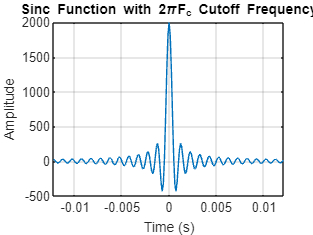


plot(t, y_t)
title("Received Signal in Time Domain")
xlabel("Time (s)")
ylabel("Amplitude")


plot_ft_rad(y_t, Fs);
title("Received Signal in Frequency Domain")

new_y = y_t.*c; %Modulate recieved signal with additional carrier signal

plot_ft_rad(new_y, Fs);
title("Recieved Signal multiplied by Carrier Frequency")


%Setup Low Pass Filter%

cutoff = 2*pi*f_c %Set the cutoff frequency for the low-pass filter

cutoff = 6.2832e+03

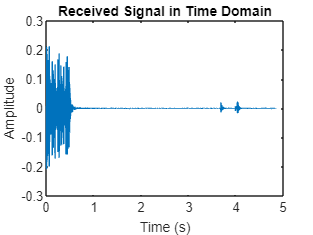

W = cutoff;	% Assign W to cutoff frequency @ 2pi*1000 rad/s
t = [-100:1:99]*(1/Fs);   % create a 200 sample time vector to generate sinc
h = W/pi*sinc(W/pi*t);   % this is the impulse response
plot(t, h);   	% plot h to visualize
title("Sinc Function with 2\piF_{c} Cutoff Frequency")
xlabel("Time (s)")
ylabel("Amplitude")
grid on


%figure
%plot_ft_rad(h, Fs)  % Visualize |H(j\omega)|
%title('Magnitude of H(j\omega)');

y = conv(new_y, h);  % convolve x with h to isolate original signal
subplot(2,1,1)
plot_ft_rad(y, Fs); % plot the magnitude of the recovered signal
title('Magnitude of Recovered Signal Frequencies');
subplot(2,1,2)
t = (0:(length(y))-1)/Fs

t =          0    0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060


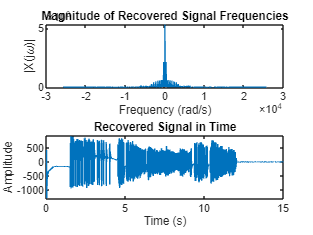

plot(t, y) % Plot recovered signal in time domain
title("Recovered Signal in Time")
ylabel("Amplitude")
xlabel("Time (s)")
hold off;

clf
% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits

y_downsample = downsample(y, 100); %Downsample signal by symbol period (100)
y_square = y_downsample(3:msg_length*8+2); % Crop signal to correct length based on message length, and 8 bits per character
% Ensure that each datapoint in the signal is either a 1 or a 0 for decoding.
y_square(y_square > 1) = 1;
y_square(y_square < 1) = 0;

stem(y_square, 'filled')
ylim([-0.1, 1.1])
title("Downsampled Binary Data")
xlabel("Bit Index")
ylabel("Bit Value")


BitsToString(y_square) % Convert bits back to message string

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...'